# Project 1: Linear Regression

## 2. Do “Exercise 3: Linear Regression” from Andrew’s Ng’s OpenClassroom online course: (Do not do the“Normal Equations” question. http://openclassroom.stanford.edu/MainFolder/DocumentPage.php?course=MachineLearning&doc=exercises/ex3/ex3.html

% import data
x = load('ex3x.dat');
y = load('ex3y.dat');

% Preprocessing
m = length(y);
% x = [ones(m,1), x];

sigma = std(x);
mu = mean(x);

x(:,1) = (x(:,1) - mu(1))./ sigma(1);
x(:,2) = (x(:,2) - mu(2))./ sigma(2);

## Selecting a learning rate using J($\theta$)

import regressor_object.*
alpha = [1,0.1,0.05,0.01,0.001];
epoch = 50;
colors = {'r','g','b','m','y'};
% lines = {'--','-.','-'}

for i = 1:5
    a = regressor_object(x,y,alpha(i),epoch);
    
%%[final_theta,cost] = linear_regressor(object,mini_batch_size)
   [final_theta,err]= linear_regressor(a,length(x)); %length(x) for batch

%%Plot regression and cost
%     plot_graph(a,final_theta,err)
    
    final_thetas(:,i) = final_theta;
    final_err(:,i) = err;
    
    
    
%      fprintf('Final theta is: %.2d \n',final_theta)

x_space = linspace(-100,100,100)';
axis_space = [min(a.feature(:,1)),max(a.feature(:,1))];
y_pred = sum(([x_space,x_space,x_space]*final_theta'),2);

subplot(1,2,1)
scatter3(a.feature(:,1),a.feature(:,end),a.target,'r')
hold on
plot3(x_space,x_space,y_pred,colors{i})           
xlabel('feature_1')
ylabel('feature_2')
zlabel('target')
xlim([min(a.feature(:,1)),max(a.feature(:,1))])
ylim([min(a.feature(:,2)),max(a.feature(:,2))])
zlim([min(a.target),max(a.target)])
legend('Training Data',num2str(alpha(1)),'location','best')
subplot(1,2,2)
plot(1:1:a.epoch,err,colors{i})
hold on
xlabel('epoch')
ylabel('J_{\theta}')
legend(num2str(alpha(1)),num2str(alpha(2)),num2str(alpha(3))...
    ,num2str(alpha(4)),num2str(alpha(5)))
end

Epoch  5: current theta values: 3.40e+05, 1.00e+05, 
 -4.49e+03. 
Epoch 10: current theta values: 3.40e+05, 1.10e+05, 
 -6.12e+03. 
Epoch 15: current theta values: 3.40e+05, 1.11e+05, 
 -6.63e+03. 
Epoch 20: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 25: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 30: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 35: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 40: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 45: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 
Epoch 50: current theta values: 3.40e+05, 1.11e+05, 
 -6.65e+03. 


Epoch  5: current theta values: 1.17e+05, 3.47e+04, 
 1.57e+04. 
Epoch 10: current theta values: 2.09e+05, 5.95e+04, 
 2.11e+04. 
Epoch 15: current theta values: 2.63e+05, 7.39e+04, 
 1.99e+04. 
Epoch 20: current theta values: 2.94e+05, 8.30e+04, 
 1.65e+04. 
Epoch 25: current theta values: 3.13e+05, 8.93e+04, 
 1.28e+04. 
Epoch 30: current theta values: 3.24e+05, 9.38e+04, 
 9.28e+03. 
Epoch 35: current theta values: 3.31e+05, 9.73e+04, 
 6.29e+03. 
Epoch 40: current theta values: 3.35e+05, 1.00e+05, 
 3.80e+03. 
Epoch 45: current theta values: 3.37e+05, 1.02e+05, 
 1.77e+03. 
Epoch 50: current theta values: 3.38e+05, 1.04e+05, 
 1.18e+02. 


Epoch  5: current theta values: 6.31e+04, 1.90e+04, 
 9.26e+03. 
Epoch 10: current theta values: 1.26e+05, 3.70e+04, 
 1.61e+04. 
Epoch 15: current theta values: 1.74e+05, 5.03e+04, 
 1.95e+04. 
Epoch 20: current theta values: 2.12e+05, 6.04e+04, 
 2.06e+04. 
Epoch 25: current theta values: 2.41e+05, 6.81e+04, 
 2.04e+04. 
Epoch 30: current theta values: 2.64e+05, 7.42e+04, 
 1.93e+04. 
Epoch 35: current theta values: 2.81e+05, 7.92e+04, 
 1.78e+04. 
Epoch 40: current theta values: 2.94e+05, 8.32e+04, 
 1.61e+04. 
Epoch 45: current theta values: 3.05e+05, 8.65e+04, 
 1.43e+04. 
Epoch 50: current theta values: 3.13e+05, 8.94e+04, 
 1.25e+04. 


Epoch  5: current theta values: 1.34e+04, 4.11e+03, 
 2.10e+03. 
Epoch 10: current theta values: 2.94e+04, 8.96e+03, 
 4.49e+03. 
Epoch 15: current theta values: 4.47e+04, 1.35e+04, 
 6.64e+03. 
Epoch 20: current theta values: 5.92e+04, 1.78e+04, 
 8.56e+03. 
Epoch 25: current theta values: 7.30e+04, 2.18e+04, 
 1.03e+04. 
Epoch 30: current theta values: 8.61e+04, 2.56e+04, 
 1.18e+04. 
Epoch 35: current theta values: 9.85e+04, 2.92e+04, 
 1.32e+04. 
Epoch 40: current theta values: 1.10e+05, 3.25e+04, 
 1.44e+04. 
Epoch 45: current theta values: 1.22e+05, 3.57e+04, 
 1.54e+04. 
Epoch 50: current theta values: 1.32e+05, 3.87e+04, 
 1.64e+04. 


Epoch  5: current theta values: 1.36e+03, 4.19e+02, 
 2.17e+02. 
Epoch 10: current theta values: 3.05e+03, 9.38e+02, 
 4.84e+02. 
Epoch 15: current theta values: 4.74e+03, 1.45e+03, 
 7.49e+02. 
Epoch 20: current theta values: 6.41e+03, 1.97e+03, 
 1.01e+03. 
Epoch 25: current theta values: 8.08e+03, 2.48e+03, 
 1.27e+03. 
Epoch 30: current theta values: 9.74e+03, 2.98e+03, 
 1.53e+03. 
Epoch 35: current theta values: 1.14e+04, 3.49e+03, 
 1.78e+03. 
Epoch 40: current theta values: 1.30e+04, 3.99e+03, 
 2.03e+03. 
Epoch 45: current theta values: 1.47e+04, 4.48e+03, 
 2.28e+03. 
Epoch 50: current theta values: 1.63e+04, 4.98e+03, 
 2.53e+03. 


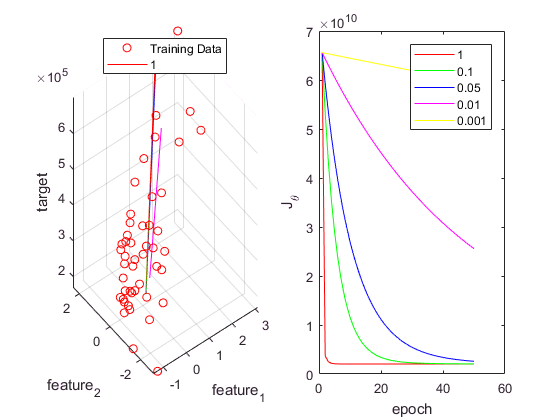

hold off

import regressor_object.*

a = regressor_object(x,y,0.1,50);
    
%%[final_theta,cost] = linear_regressor(object,mini_batch_size)
[final_theta,err]= linear_regressor(a,length(x)); %length(x) for batch

Epoch  5: current theta values: 1.17e+05, 3.47e+04, 
 1.57e+04. 
Epoch 10: current theta values: 2.09e+05, 5.95e+04, 
 2.11e+04. 
Epoch 15: current theta values: 2.63e+05, 7.39e+04, 
 1.99e+04. 
Epoch 20: current theta values: 2.94e+05, 8.30e+04, 
 1.65e+04. 
Epoch 25: current theta values: 3.13e+05, 8.93e+04, 
 1.28e+04. 
Epoch 30: current theta values: 3.24e+05, 9.38e+04, 
 9.28e+03. 
Epoch 35: current theta values: 3.31e+05, 9.73e+04, 
 6.29e+03. 
Epoch 40: current theta values: 3.35e+05, 1.00e+05, 
 3.80e+03. 
Epoch 45: current theta values: 3.37e+05, 1.02e+05, 
 1.77e+03. 
Epoch 50: current theta values: 3.38e+05, 1.04e+05, 
 1.18e+02. 


axis_space =    -1.4454    3.1173


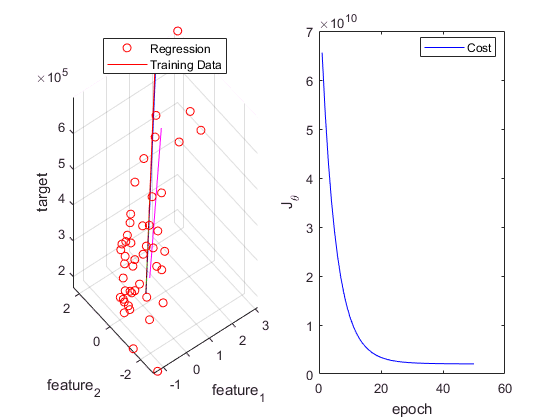


plot_graph(a,final_theta,err);

## Use the best learning rate you found, show final values of $\theta$

fprintf('Final theta: %d \n',final_theta)

Final theta: 3.386583e+05 
Final theta: 1.041275e+05 
Final theta: -1.722051e+02 


## Predicted price of a house with 1650 sq ft and 3 bedrooms

pred_house = sum(final_theta.*[1,((1650-mu(1))/sigma(1)),((3-mu(2))/sigma(2))]);
fprintf('Predicated house price with 1650 sq ft and 3 bedrooms: %.1f',pred_house);

Predicated house price with 1650 sq ft and 3 bedrooms: 292748.1